gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab')
changeCobraSolver('gurobi', 'all')


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

ans = logical
   1


## Load the data

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx');
% Housekeeping genes with the ensembl ids
h_k_g = readtable('NM2ENSG.xlsx');
% Human1 metabolic model.
model = load('Human-GEM_Cobra_v1.01.mat')

model = struct with fields:
    model: [1×1 struct]


model = model.model

model = struct with fields:
                      S: [8365×13026 double]
                     lb: [13026×1 double]
                     ub: [13026×1 double]
                      c: [13026×1 double]
                   rxns: {13026×1 cell}
               rxnNames: {13026×1 cell}
             subSystems: {13026×1 cell}
               rxnNotes: {13026×1 cell}
            metFormulas: {8365×1 cell}
                  comps: {9×1 cell}
              compNames: {9×1 cell}
             metCharges: [8365×1 int64]
                  genes: {3068×1 cell}
    rxnConfidenceScores: [13026×1 double]
             rxnGeneMat: [13026×3068 double]
                    rev: [13026×1 double]
                   mets: {8365×1 cell}
                modelID: 'Human-GEM'
           rxnECNumbers: {13026×1 cell}
                version: '1.13.0'
            description: 'Generic genome-scale metabolic model of Homo sapiens'
          rxnReferences: {13026×1 cell}
               metNames: {8365×1 cell}
         metI

## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes

model_genes = 3068×1 cell array
    {'ENSG00000000419'}
    {'ENSG00000001036'}
    {'ENSG00000001084'}
    {'ENSG00000001630'}
    {'ENSG00000002549'}
    {'ENSG00000002587'}
    {'ENSG00000002726'}
    {'ENSG00000002746'}
    {'ENSG00000003137'}
    {'ENSG00000003987'}
    {'ENSG00000003989'}
    {'ENSG00000004455'}
    {'ENSG00000004468'}
    {'ENSG00000004478'}
    {'ENSG00000004779'}
    {'ENSG00000004799'}
    {'ENSG00000004809'}
    {'ENSG00000004864'}
    {'ENSG00000004939'}
    {'ENSG00000004961'}
    {'ENSG00000005022'}
    {'ENSG00000005075'}
    {'ENSG00000005187'}
    {'ENSG00000005339'}
    {'ENSG00000005381'}
    {'ENSG00000005421'}
    {'ENSG00000005469'}
    {'ENSG00000005471'}
    {'ENSG00000005483'}
    {'ENSG00000005810'}


% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :)

data_met = 3033×49 table
      Ensembl_GeneID         BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3    IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD

## StanDep

The first step is to check the if the model contain blocked reactions that can affect the interpretation. 

%First, in all model extraction it is good to pre_process the model to
%ensure it does not contain blocked reactions

[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
model = fluxConsistModel

model = struct with fields:
                          S: [7114×11831 double]
                         lb: [11831×1 double]
                         ub: [11831×1 double]
                          c: [11831×1 double]
                       rxns: {11831×1 cell}
                   rxnNames: {11831×1 cell}
                 subSystems: {11831×1 cell}
                   rxnNotes: {11831×1 cell}
                metFormulas: {7114×1 cell}
                      comps: {9×1 cell}
                  compNames: {9×1 cell}
                 metCharges: [7114×1 int64]
                      genes: {2495×1 cell}
        rxnConfidenceScores: [11831×1 double]
                 rxnGeneMat: [11831×2495 double]
                        rev: [11831×1 double]
                       mets: {7114×1 cell}
                    modelID: 'Human-GEM'
               rxnECNumbers: {11831×1 cell}
                    version: '1.13.0'
                description: 'Generic genome-scale metabolic model of Homo sapiens'
        

model

model = struct with fields:
                          S: [7114×11831 double]
                         lb: [11831×1 double]
                         ub: [11831×1 double]
                          c: [11831×1 double]
                       rxns: {11831×1 cell}
                   rxnNames: {11831×1 cell}
                 subSystems: {11831×1 cell}
                   rxnNotes: {11831×1 cell}
                metFormulas: {7114×1 cell}
                      comps: {9×1 cell}
                  compNames: {9×1 cell}
                 metCharges: [7114×1 int64]
                      genes: {2495×1 cell}
        rxnConfidenceScores: [11831×1 double]
                 rxnGeneMat: [11831×2495 double]
                        rev: [11831×1 double]
                       mets: {7114×1 cell}
                    modelID: 'Human-GEM'
               rxnECNumbers: {11831×1 cell}
                    version: '1.13.0'
                description: 'Generic genome-scale metabolic model of Homo sapiens'
        

Change the name of the column that contains the Ensembl_ID to gene, and normalize the data, 

%Ensuring that the first colum is names 'gene' 
data_met.Properties.VariableNames{1} = 'gene';
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met

datalog10 = 3033×49 table
           gene              BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3    IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_P

datalog10{:,2:end} = log10(datalog10{:,2:end}+1)

datalog10 = 3033×49 table
           gene              BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3     IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1     IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF

Define the limits of the bins:

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

Pre-processing of the data for Standep

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data.Properties.VariableNames(2:end)';

Pre-processing of the metabolic model

%2nd the model data structure
modelData = getModelData(rnaData,model);

Pre-processing of the enzyme data 

%3rd the enzyme data structure
spec = getSpecialistEnzymes(model);  
prom = getPromEnzymes(model);
enzymeData = comparePromiscuousSpecific(spec,prom,modelData);

Set the parameters for the clustering analysis

% We then set our parameters...
distMethod = 'euclidean'; % distance method  maybe think one more robust than euclidean.
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
k = 10;

Clustering analysis

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.8784


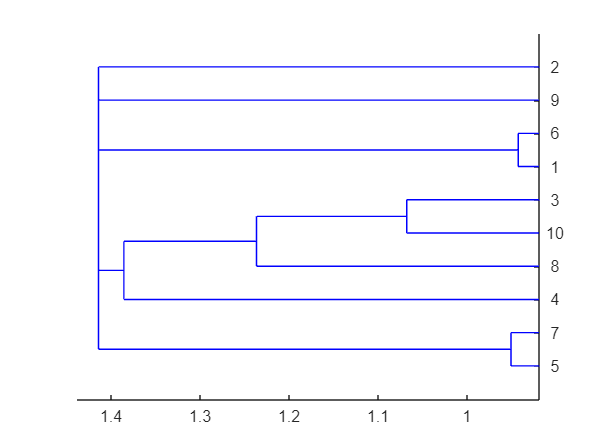

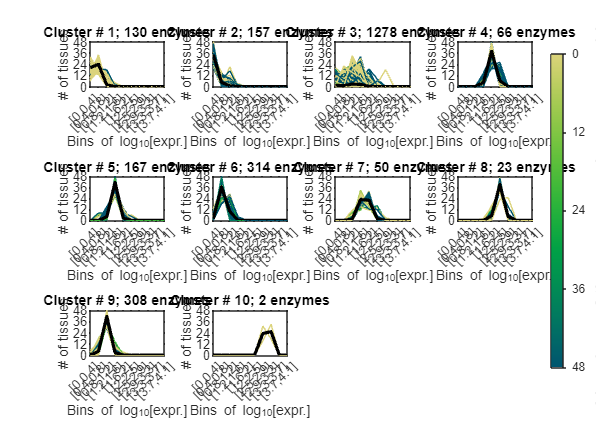

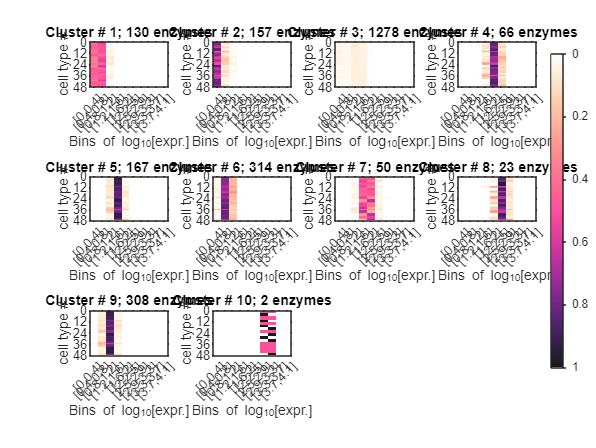

clustObj = struct with fields:
     Distribution: [2495×10 double]
          numObjs: [2495×1 double]
          objects: {2495×1 cell}
       objectMaps: {2495×1 cell}
                C: [10×10 double]
           cindex: [2495×1 double]
             Data: [2495×48 double]
    numObjInClust: [10×1 double]


close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy(enzymeData,[],edgeX,k,distMethod,linkageMethod)

Identify core reactions and calculate ubiquity score?

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense

Top 25th percentile for the data = 1.0211
Mean of Data = 0.1716
Std. Dev. of Data = 0.2575
fraction selected = 0.0002
fraction selected = 0.0001
fraction selected = 0.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000


[ubiScore,uScore] = getUbiquityScore_2022(clustObj,edgeX,model); %ubiScore is the ubiquity score per rxns to use in mCadre!

Top 25th percentile for the data = 1.0211
Mean of Data = 0.1716
Std. Dev. of Data = 0.2575


# HOUSEKEEPING GENES 

ens_hkg = h_k_g.converted_alias;
% Check which ones are metabolic
% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(ens_hkg, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
met_hkg = ens_hkg(index_names)

met_hkg = 774×1 cell array
    {'ENSG00000000419'}
    {'ENSG00000001084'}
    {'ENSG00000002549'}
    {'ENSG00000004455'}
    {'ENSG00000004961'}
    {'ENSG00000005022'}
    {'ENSG00000005075'}
    {'ENSG00000005882'}
    {'ENSG00000006007'}
    {'ENSG00000006625'}
    {'ENSG00000007168'}
    {'ENSG00000009335'}
    {'ENSG00000010165'}
    {'ENSG00000010256'}
    {'ENSG00000011052'}
    {'ENSG00000011275'}
    {'ENSG00000012232'}
    {'ENSG00000012963'}
    {'ENSG00000013288'}
    {'ENSG00000013561'}
    {'ENSG00000015532'}
    {'ENSG00000016864'}
    {'ENSG00000017260'}
    {'ENSG00000017797'}
    {'ENSG00000018510'}
    {'ENSG00000023572'}
    {'ENSG00000023697'}
    {'ENSG00000023909'}
    {'ENSG00000024048'}
    {'ENSG00000027847'}



reactions_hkg = findRxnsFromGenes(model, met_hkg)

reactions_hkg = struct with fields:
    gene_ENSG00000000419: {2×5 cell}
    gene_ENSG00000001084: {'MAR04324'  'MAM01371[c] + MAM01628[c] + MAM01974[c]  -> MAM01285[c] + MAM01927[c] + MAM02039[c] + MAM02751[c] '  {1×1 cell}  'L-glutamate:L-cysteine gamma-ligase (ADP-forming)'  'ENSG00000001084 and ENSG00000023909'}
    gene_ENSG00000002549: {3×5 cell}
    gene_ENSG00000004455: {3×5 cell}
    gene_ENSG00000005022: {'MAR06328'  'MAM01285[c] + MAM01371[m]  <=> MAM01285[m] + MAM01371[c] '  {1×1 cell}  'ATP:ADP phosphatransferase'  'ENSG00000005022 or ENSG00000151729 or ENSG00000169100'}
    gene_ENSG00000005075: {2×5 cell}
    gene_ENSG00000005882: {1×5 cell}
    gene_ENSG00000006625: {2×5 cell}
    gene_ENSG00000007168: {2×5 cell}
    gene_ENSG00000010256: {1×5 cell}
    gene_ENSG00000011052: {34×5 cell}
    gene_ENSG00000012232: {5×5 cell}
    gene_ENSG00000013288: {'MAR07428'  'MAM00141[l] + 2 MAM02040[l]  -> MAM01382[l] + 2 MAM02453[l] '  {1×1 cell}  ''  'ENSG00000013288 or ENSG000001

save('reactions_hkg.mat', 'reactions_hkg');

Create an array with all the housekeeping reactions

% Suppose your structure is called 'structure'.
fields = fieldnames(reactions_hkg); % Gets the names of the fields of the structure
housekeep_react = {}; % Initialise a cell array to store the reactions and names.

% Go through each field of the structure
for i = 1:length(fields)
    field = fields{i}; % Name of the current field
    cellArray = reactions_hkg.(field); % Cell array within the current field

    % Go through each cell within the cell array
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1}; % Get the first column of the cell
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react;

Check the repeated elements

% Finding unique elements and their frequency
[uniques, ~, index] = unique(housekeep_react);
frequencies = histc(index, 1:numel(uniques));

% Identify repeated elements
repeated_elements = uniques(frequencies > 1);

% Show repeated items
disp('Repeted elements:');

Repeted elements:


disp(repeated_elements);

    {'MAR00030'}
    {'MAR00032'}
    {'MAR00080'}
    {'MAR00158'}
    {'MAR00190'}
    {'MAR00453'}
    {'MAR00456'}
    {'MAR00458'}
    {'MAR00459'}
    {'MAR00562'}
    {'MAR00580'}
    {'MAR00588'}
    {'MAR00589'}
    {'MAR00590'}
    {'MAR00591'}
    {'MAR00592'}
    {'MAR00593'}
    {'MAR00594'}
    {'MAR00596'}
    {'MAR00597'}
    {'MAR00598'}
    {'MAR00599'}
    {'MAR00600'}
    {'MAR00601'}
    {'MAR00602'}
    {'MAR00633'}
    {'MAR00645'}
    {'MAR00730'}
    {'MAR00759'}
    {'MAR00762'}
    {'MAR00765'}
    {'MAR00767'}
    {'MAR00777'}
    {'MAR00795'}
    {'MAR00797'}
    {'MAR00804'}
    {'MAR00807'}
    {'MAR00808'}
    {'MAR00821'}
    {'MAR00828'}
    {'MAR00833'}
    {'MAR00836'}
    {'MAR00872'}
    {'MAR00924'}
    {'MAR00925'}
    {'MAR00926'}
    {'MAR00927'}
    {'MAR00952'}
    {'MAR00960'}
    {'MAR00963'}
    {'MAR00968'}
    {'MAR00972'}
    {'MAR00974'}
    {'MAR00975'}
    {'MAR00977'}
    {'MAR00978'}
    {'MAR00982'}
    {'MAR01001'}
    {'MAR01005

length(repeated_elements)

ans = 860